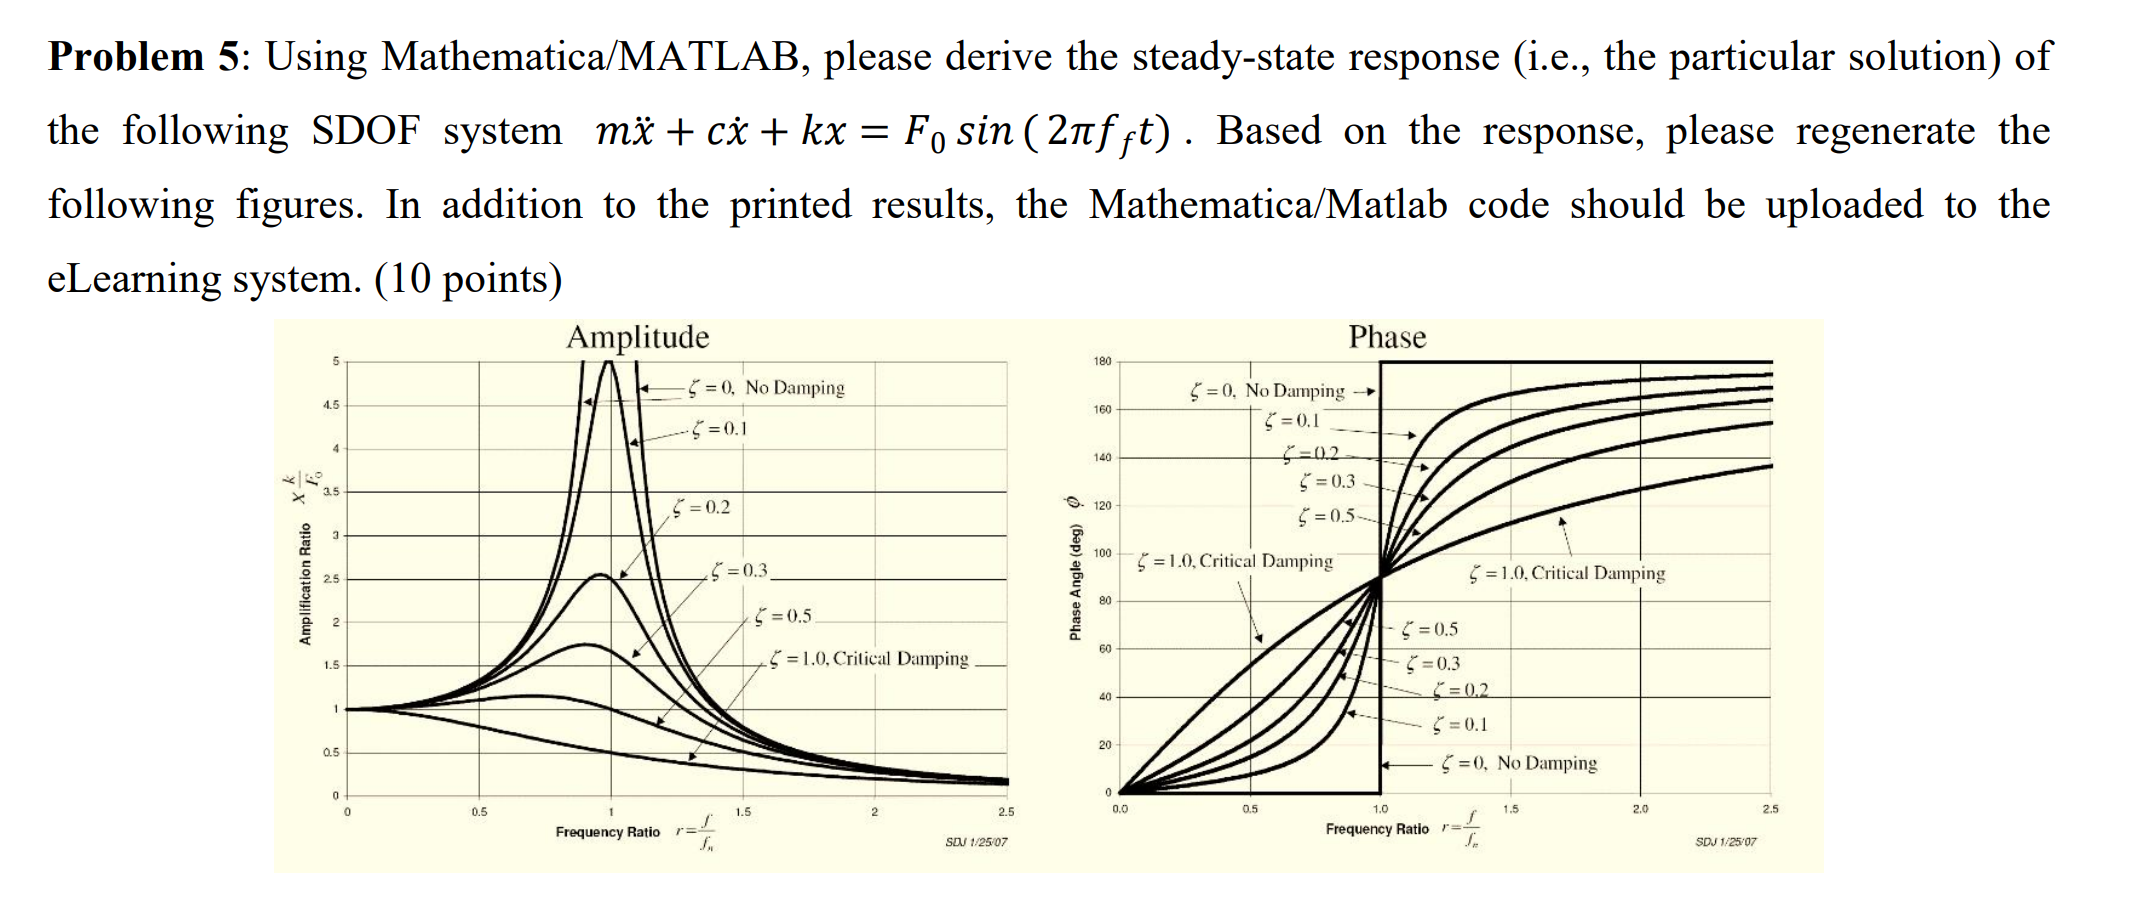

clear; clc;
syms t x(t) c k F_0 omega_f m
f = @(v) m * diff(x, 2) + c * diff(v, 1) + k * v;
eq = f(x) == F_0 * sin(omega_f*t)

$$eq(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+c\,\frac{\partial }{\partial t}x\left(t\right)+k\,x\left(t\right)=F_{0}\,\sin\left(\omega_{f}\,t\right)$$

assume(m > 0); % 添加条件 m > 0
assume(k > 0); % 添加条件 k > 0
res = dsolve(eq)

$$res = \begin{array}{l} C_{2}\,\sigma_{3}+C_{1}\,\sigma_{2}+\frac{F_{0}\,\sigma_{3}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{4}}{2\,m}}\,\left(\sigma_{1}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{4}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{4}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{4}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{4}}{2\,m}}\,\sigma_{2}\,\left(\sigma_{1}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{4}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{4}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{4}}\\ \mathrm{where}\\ \sigma_{1}=\omega_{f}\,\cos\left(\omega_{f}\,t\right)\\ \sigma_{2}={\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{4}\right)}{2\,m}}\\ \sigma_{3}={\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{4}\right)}{2\,m}}\\ \sigma_{4}=\sqrt{c^{2}-4\,k\,m} \end{array}$$

syms C1 C2
x_p = subs(res, [C1 C2], [0 0])

$$x\_p = \begin{array}{l} \frac{F_{0}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{1}\right)}{2\,m}}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{1}}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{1}}{2\,m}}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{1}\right)}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{c^{2}-4\,k\,m}\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right) \end{array}$$

x_h= res - x_p

$$x\_h = C_{2}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}}+C_{1}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}}$$

check_res = f(res)

$$check\_res(t) = \begin{array}{l} m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-c\,\left(\frac{C_{1}\,\sigma_{3}\,\left(c-\sigma_{9}\right)}{2\,m}+\frac{C_{2}\,\sigma_{4}\,\left(c+\sigma_{9}\right)}{2\,m}+\frac{F_{0}\,\sigma_{4}\,\sigma_{8}\,\left(\sigma_{1}+\frac{\omega_{f}\,\cos\left(\omega_{f}\,t\right)\,\left(c+\sigma_{9}\right)}{2\,m}\right)}{\sigma_{6}}-\frac{F_{0}\,\sigma_{7}\,\sigma_{3}\,\left(\sigma_{1}+\frac{\omega_{f}\,\cos\left(\omega_{f}\,t\right)\,\left(c-\sigma_{9}\right)}{2\,m}\right)}{\sigma_{5}}\right)+k\,\left(C_{2}\,\sigma_{4}+C_{1}\,\sigma_{3}+\frac{F_{0}\,\sigma_{4}\,\sigma_{8}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{9}\right)}{2\,m}\right)}{\sigma_{6}}-\frac{F_{0}\,\sigma_{7}\,\sigma_{3}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{9}\right)}{2\,m}\right)}{\sigma_{5}}\right)\\ \mathrm{where}\\ \sigma_{1}={\omega_{f}}^{2}\,\sin\left(\omega_{f}\,t\right)\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right)\\ \sigma_{3}={\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{9}\right)}{2\,m}}\\ \sigma_{4}={\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{9}\right)}{2\,m}}\\ \sigma_{5}=\left(\frac{{\left(c-\sigma_{9}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{9}\\ \sigma_{6}=\left(\frac{{\left(c+\sigma_{9}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{9}\\ \sigma_{7}={\mathrm{e}}^{\frac{c\,t-t\,\sigma_{9}}{2\,m}}\\ \sigma_{8}={\mathrm{e}}^{\frac{c\,t+t\,\sigma_{9}}{2\,m}}\\ \sigma_{9}=\sqrt{c^{2}-4\,k\,m} \end{array}$$

check_x_h = f(x_h)

$$check\_x\_h(t) = \begin{array}{l} m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-c\,\left(\frac{C_{1}\,\sigma_{1}\,\left(c-\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}+\frac{C_{2}\,\sigma_{2}\,\left(c+\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}\right)+k\,\left(C_{2}\,\sigma_{2}+C_{1}\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{t\,\left(c-\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}}\\ \sigma_{2}={\mathrm{e}}^{-\frac{t\,\left(c+\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}} \end{array}$$

check_x_p = f(x_p)

$$check\_x\_p(t) = \begin{array}{l} m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-c\,\left(\frac{F_{0}\,\sigma_{8}\,\sigma_{6}\,\left(\sigma_{1}+\frac{\omega_{f}\,\cos\left(\omega_{f}\,t\right)\,\left(c+\sigma_{9}\right)}{2\,m}\right)}{\sigma_{4}}-\frac{F_{0}\,\sigma_{5}\,\sigma_{7}\,\left(\sigma_{1}+\frac{\omega_{f}\,\cos\left(\omega_{f}\,t\right)\,\left(c-\sigma_{9}\right)}{2\,m}\right)}{\sigma_{3}}\right)+k\,\left(\frac{F_{0}\,\sigma_{8}\,\sigma_{6}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{9}\right)}{2\,m}\right)}{\sigma_{4}}-\frac{F_{0}\,\sigma_{5}\,\sigma_{7}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{9}\right)}{2\,m}\right)}{\sigma_{3}}\right)\\ \mathrm{where}\\ \sigma_{1}={\omega_{f}}^{2}\,\sin\left(\omega_{f}\,t\right)\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right)\\ \sigma_{3}=\left(\frac{{\left(c-\sigma_{9}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{9}\\ \sigma_{4}=\left(\frac{{\left(c+\sigma_{9}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{9}\\ \sigma_{5}={\mathrm{e}}^{\frac{c\,t-t\,\sigma_{9}}{2\,m}}\\ \sigma_{6}={\mathrm{e}}^{\frac{c\,t+t\,\sigma_{9}}{2\,m}}\\ \sigma_{7}={\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{9}\right)}{2\,m}}\\ \sigma_{8}={\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{9}\right)}{2\,m}}\\ \sigma_{9}=\sqrt{c^{2}-4\,k\,m} \end{array}$$

A = abs(x_p)

$$A = \begin{array}{l} \left|\frac{F_{0}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{1}\right)}{2\,m}}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{1}}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{1}}{2\,m}}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{1}\right)}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}\right|\\ \mathrm{where}\\ \sigma_{1}=\sqrt{c^{2}-4\,k\,m}\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right) \end{array}$$

phi = angle(x_p)

$$phi = \begin{array}{l} \text{angle}\left(\frac{F_{0}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{1}\right)}{2\,m}}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{1}}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{1}}{2\,m}}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{1}\right)}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{c^{2}-4\,k\,m}\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right) \end{array}$$